# Lab 9 - SenseyArduino

------------------------------------------------------------------------------------------------------------------------------------------------------

Created: 27 October 2019

By: Samuel Bechara and Joshua Christopher

## Introduction

This week we are going to check out a really cool sensor that came with your Arduino kit: the ultrasonic sensor! This sensor sends out a very high frequency pulse that bounces off objects and returns to the sensor. Distance can then be measured by timing how long it took for the sound to make the trip from sensor to object and back to the sensor. It works exactly the same way as a...

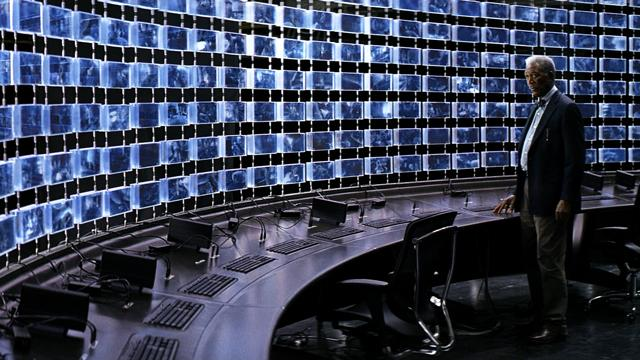

submarine, Mr. Wayne. Like a submarine. Unfortunately this lab is coming a day late for finding clowns this Halloween. Fortunately there are plenty of other uses for ultrasonic sensors, such as a safety feature in cars that will hit the brakes for you to prevent rear endings. If you have driven or taken a ride in a Tesla that has this feature, you know that the car dings very loundly at you as it applies the brakes. So in that spirit, we are also going to attach a very annoying buzzer to our range sensor that lets us know if we are getting too close. The piezo speaker that we are going to be using has some piezoelectric material (I'll let you search for what that is) that a voltage is applied to. The piezoelectric material then vibrates at a frequency that is turned into sound via resonators. Cool, lets make some noise with it!

This lab will have less guidance than previous labs. We will show you some diagrams and photos for how to build the circuit and provide some outlines on how to use the sensor and speaker, so you should have enough experience and resources to figure out how to complete the lab. I highly recommend you follow the guidelines of Chapter 12 of your textbook in creating a plan of attack for this lab. Before you start coding, write out what you expect to happen for the inputs from the sensor.

Hardware Requirements:

- 5 LEDS (2 Red, 1 Yellow, 2 Green)

- 5 resistors

- Ultrasonic Sensor

- Speaker

- A whole bunch of jumpers

Like previous labs, we have a hardware section and a software section.

## The Hardware

As I mentioned above, the ultrasonic sensor sends out a pulse and listens for how long it takes to reflect off an object.

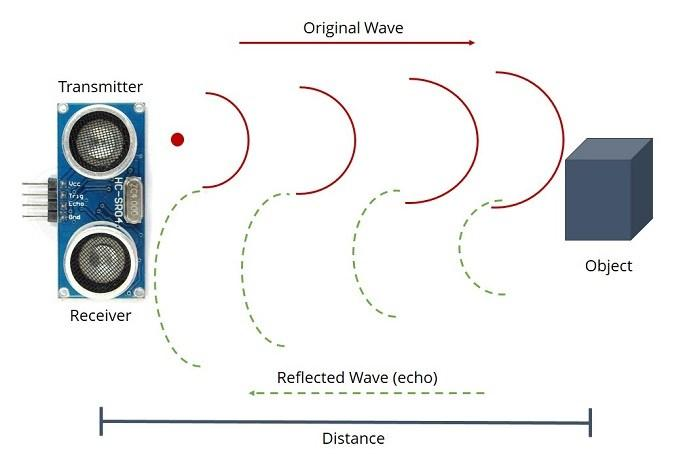

The speed of sound in air can be used to figure out how far something is. The speed of sound is calculated with:


$$a = \sqrt{\gamma RT}$$


where $\gamma$is the specific heat ratio (typically can just treat it as a constant 1.4), R is the gas constant, and T is temperature in Kelvin. Fortunately we don't need to worry about this because MATLAB will take care of it for us. What we need to focus on is which pin on the sensor goes where. Take a look at the sensor and notice that each pin is labeled. Vcc is your positive voltage pin, Gnd is your ground. The pin labeled Trig is for sending out the pulse, and Echo is for listening to the response. [More info and the data sheet for the ultrasonic sensor can be found here.](https://www.sparkfun.com/products/13959)

The piezo speaker only as two pins, take a look at the bottom to see which is which. The negative side is your ground and the positive side is your input. [More info and the data sheet for the piezo speaker can be found here.](https://www.sparkfun.com/products/7950) I've shown an example of how you can hook this up in the diagram below.

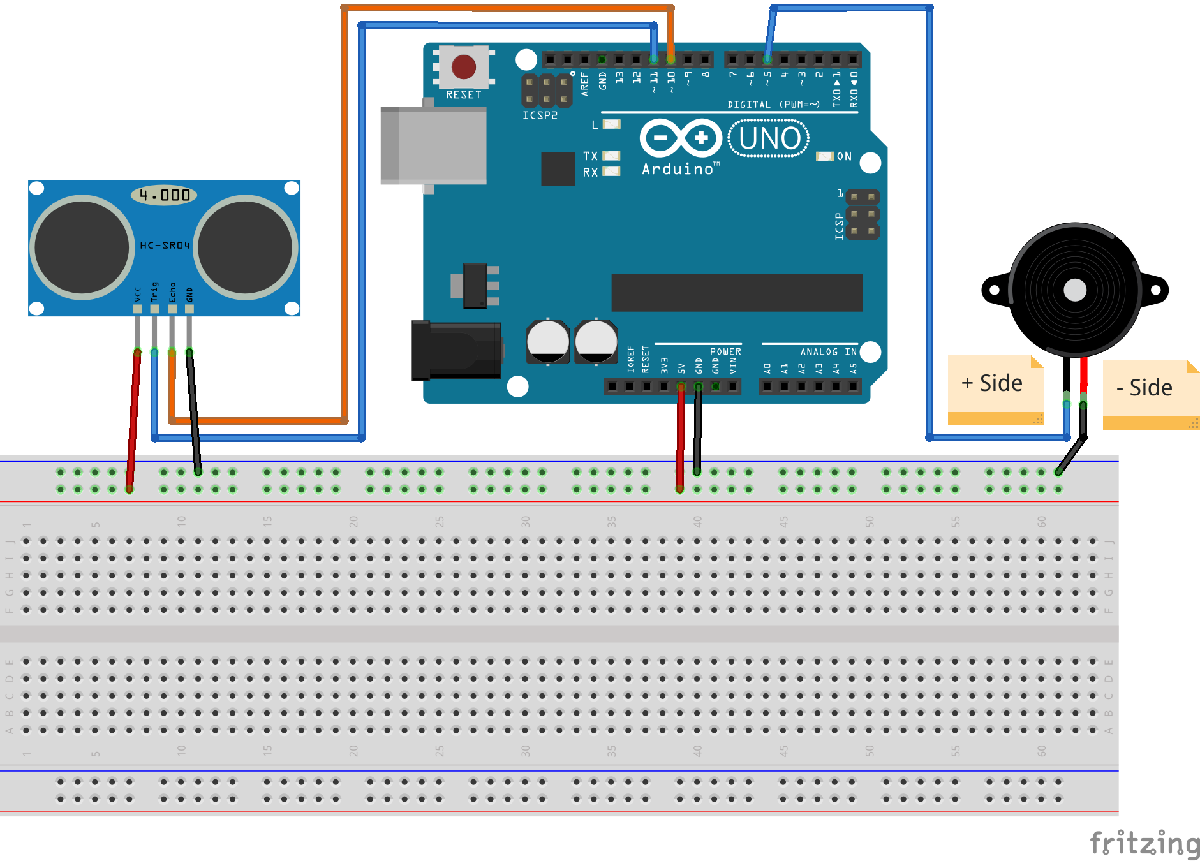

## The Software

We will learn a few new Matlab functions this week to work with the ultrasensor and piezo speaker. As we have introduced new functions every week, it might be a good idea to create flashcards for these functions so you can practice memorizing them, what they do, and how to call them.

### Ultracool Ultrasonic

Setting up the Arduino for using the ultrasonic sensor is a little more complex than usual. Using the ultrasonic sensor requires MATLAB to upload a bit more code to the Arduino. You might be able to set up the Arduino for the ultrasonic sensor by using MATLAB's `arduinosetup` function in the Command Window.

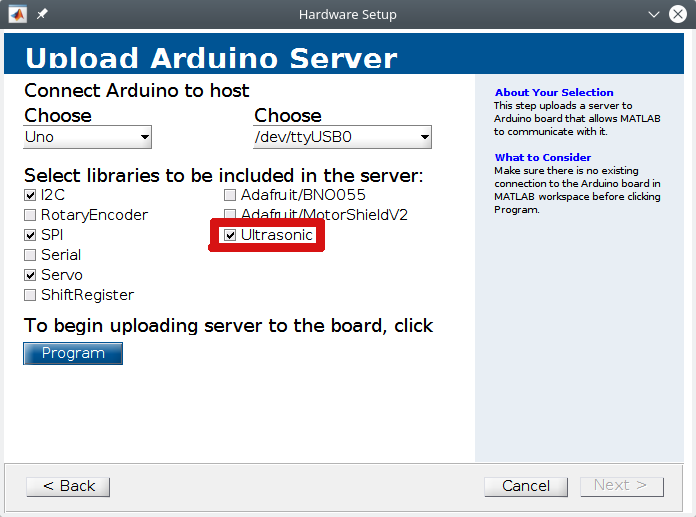

If that doesn't work, then we can add it to the `arduino` function as shown below. After creating the `arduino` object we need to set up the ultrasonic sensor using the `ultrasonic` function. It has function arguments are the Arduino, the trigger pin, and the echo pin. Once that is all set up we can read distance using the `readDistance` function which has one argument of the ultrasonic sensor object we created with the `ultrasonic` function. See the code below.

TRIG_PIN = 'D8';
ECHO_PIN = 'D7';
% Setup arduino object
sensyArduino = arduino('/dev/ttyUSB0','Uno','libraries','ultrasonic');
% Setup ultrasonic sensor
ultraSensor = ultrasonic(sensyArduino,TRIG_PIN,ECHO_PIN);
for numTests = 1:20
    distance = readDistance(ultraSensor) % omit ; so you can see in command window
    pause(0.25)
end

This will read the distance in meters every quarter second for 5 seconds. Use MATLAB's help functions to learn more about each of these functions. 

### Not so ultra sonic, noise we can actually hear

Using the piezo speaker is quite a bit easier, using the `playTone` function. This function has four arguments:

- The Arduino object

- Which pin the positive side the piezo speaker is connected to

- The frequency of the tone you want to play

- The number of seconds you want to play the tone

SPEAK_PIN = 'D9';
playTone(sensyArduino,SPEAK_PIN,440,1);

This will play a 440Hz tone for 1 second. If you play an instrument, you probably know that 440Hz is the A4 tone. You can check out this chart on Wikipedia for which frequencies correspond to which notes: [Piano Key Frequencies](https://en.wikipedia.org/wiki/Piano_key_frequencies). Using this chart you can make your piezo speaker play little melodies like "twinkle twinkle little star" (or entire songs if you have the patience to program it all). 

### Introducing a new way to digital pin: the PWM!

On your Arduino, some of the digital pins have a little tilde (~) next to the number, for example pin 9 is written "~9". This tilde indicates that it is a PWM pin, which stands for Pulse Width Modulation. PWM is a technique for writing out an anlog signal on a digital pin. Normally with digital pins you can only write a one or zero, high or low voltage. When writing analog to a PWM pin, you can send any value between 0 and 255 where an analog value of 255 is the same thing as writing a digital 1 and an analog value of 0 is the same as... well a digital 0. For the values in between, the Arduino will cycle the output on the digital pin between 1 and 0 at some frequency as shown in the figure below.

 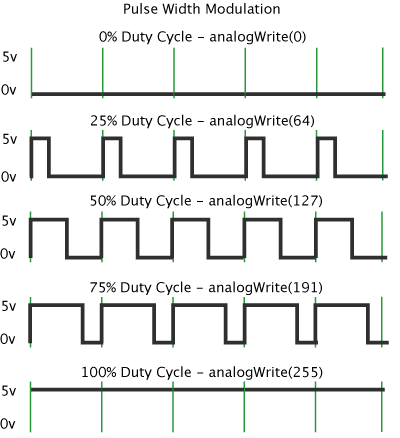

If you connect your speaker to a PWM pin, you can then write out PWM signals to the speaker. We can use Matlab's `writePWMDutyCycle` function to play sounds from the speaker at different pitches. It has three arguments:

- The arduino object

- The pin the speaker is connected to

- The duty cycle you want to play as value between 0 and 1 that is the perecentage of 100% duty cycle

We use it this way:

SPEAK_PIN = 'D9';
duty_cylcle = 0.45;
writePWMDutyCycle(sensyArduino, SPEAK_PIN, duty_cycle);

Go ahead and connect your speaker to a PWM pin and play a couple different duty cycles through it. As you increase the duty cycle, does the pitch played get higher or lower? I really don't know, despite playing piano and violin for years I am completely tone deaf so let me know.

### Nesting if statements

Sometimes we need to do something called nested if statements. This is a bit of a funny name for them because we aren't putting them in bird nests. A nested if statement is the term for when we put one if statement inside of another if statement, kind of like those Russian dolls:

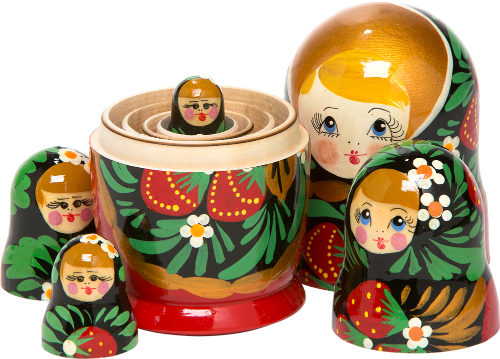

We use nested if statements when we want to check multiple things. Lets say we are using the ultrasonic sensor and the temperature sensor. Lets go back to the auto-braking feature from the introduction. If the temperature is below freezing there may be ice on the road and so we want to warn the driver to brake sooner than when it is above freezing (since it will take longer to brake). We have two checks to make: 

- Is the temperature above or below freezing?

- Is our current following distance safe for the current temperature?

Here is an example of what nested if statements look like:

% Normally get both these measurements from a sensor
distance = 5.6; % Current follow distance in meters
temperature = -5; % Celsius

if(temperature > 0)
    if (distance < 3)
        % Warn the driver with lights and sounds
    elseif (distance < 5)
        % Warn the driver with lights
    end
else
    if (distance < 5)
        % Warn the driver with lights and sounds
    elseif (distance < 7)
        % Warn the driver with lights
    end
end

Notice how we first check temperature to see if we are above or below freezing. If we are above freezing, we use a nested if statement to check the distance and see how much to warn the driver. If we are below freezing, we have a nested if statement using different distances to decide how much to warn the driver.

How many nests can you make with nested statements? As many as you like! Maybe you have a third sensor you want to check the values, you can nest that inside the distance if statement above.

## The Deliverable

We are going to recreate the Tesla rear-end autobraking, except without the brakes. We'll call this a prototype for our new car company: Breadboard Revolution Automotive Kit Enterprises, or BRAKE. Instead of a warning light on the display console, we are going to use LEDs as a visual indicator. Hook up 5 LEDs to your circuit that already has a working ultrasonic sensor and piezo speaker. Use 2 green LEDs, 1 yellow, and 2 reds. Before you write the code, create a flowchart that plans out what you want the Arduino project to do. Turn in your flowchart to Canvas (scan it, or create it in a flow chart program and save as a picture and upload the picture). Then create a code to run the project that matches the following specifications:

- If object is sensed further than 2 meters away, the both green LEDs are lit.

- If object is sensed between 2 and 1 meters away, only 1 green LED is lit.

- If object is sensed between 1.25 and 0.75 meter away the yellow LED is lit.

- If object is sensed between 1 and 0.75 meters away, 1 red LED is lit.

- If object is sensed between 0.75 and 0 meters away 2 red LEDs are lit.

- If object is sensed between 0 and 1 meters away, a sound is emitted with a PWM duty cycle equal to the distance. (i.e. if the object is 0.34 meters away, a sound is emitted by activating the spearker with a PWM duty cycle of 0.34).

Make sure to stick your conditionals into a loop of some sort so that it checks the distance at least once per second. Once you have created the circuit and programmed it, show it to your LA. If you don't have enough time this lab, show it to your LA at the start of next week's lab. The flowchart is also due by the start of next week's lab.

### A code template

% Note: must do new arduinosetup and make sure ultrasonic is selected
clear;close all;clc;

% Define Pins

% Setup arduino object, make sure to set up the arduino for ultrasonic
% as described above!


% Setup ultrasonic sensor

% This while loop will run forever, so we will stick our distance reading,
% LED lighting, and noise making inside of here
while(1)
    % Read the distance from the ultrasonic sensor
    
    
    % Use nested if statements to check distance and decide
    % Whether or not to play a sound

    
    
    
    
    % Use a pause so we aren't taking a million distance readings per
    % second
    pause(0.5);
end